# **N-S equation solver ( unsteady incompressible 2D)**

**Author:- Kshitij Gupta (developed as a part of internship at IITD)**

Solving the incompressible Navier-Stokes equations using staggered-grid, i.e u and v velocity is solved on edge and pressure p is solved at grid centre.

Base Tank excitation: boundary condition number == 4

**Second-order Adams-Bashforth method**

It's an explicit method used to approximate the solution of ordinary differential equations (ODEs). 

$\frac{\textrm{dy}}{\textrm{dt}}=f\left(t,y\right)$, with intial condition $y\left(t_o \right)=y_o$, $y\left(t_n \right)$ ca be approxinated at later time $t_n =t_o +\textrm{nh}\ldotp$ (h is time step) as


$$y_{n+1} =y_n +\frac{h}{2}\left(3f\left(t_n ,y_n \right)-f\left(t_{n-1} ,y_{n-1} \right)\right)$$


where $y_n \;,\;$$y_{n-1}$are the previously corrected values of $y\left(t\right)$ at time steps $t_{n\;,\;}$$t_{n-1}$

**Block LU decomposition**

Block LU decomposition is a variant of LU decomposition tailored for structured matrices,

LU decomposition, short for "Lower-Upper" decomposition. It decomposes a square matrix $A$ into the product of a lower triangular matrix $L$ and an upper triangular matrix $U\ldotp$


$$A=\textrm{LU}$$


where 

- A is the original coefficient matrix.

- L is a lower triangular matrix with ones on its diagonal.

- U  is an upper triangular matrix.

Step 1: Decompose the original matrix $A$ into the product of $L$ and $U$

Step 2:  Solve the equation for $\textrm{Ly}=b$ for $y$ using forward substitution.

Step 3:Solve the equation $\textrm{Ux}=y$ for $x\;$using backward substitution.

**Fractional Step Method:**

This scheme is used for solving time-dependent PDEs, particularly Navier-Stokes equations in fluid dynamics. It splits the solution process into multiple steps, typically by decoupling the equations governing different physical phenomena (such as convection, diffusion, and pressure)

**Conjugate gradient method matrix solver**:- method is an iterative algorithm used to solve systems of linear equations of the form $\textrm{Ax}=b$ where $A$ is a symmetric positive definite matrix.

Step 1: Start with an initial guess for the solution $x^{\left(0\right)}$, and set the residual $r^{\left(0\right)} =b-Ax^{\left(0\right)}$ and the search direction $p^{\left(0\right)} =r^{\left(0\right)} \ldotp$

Step 2:  At each iteration $k:$

- Compute the step size $\alpha_k \;$by minimizing the residual along the search direction: $\alpha_k =\frac{r^{\left(k\right)T} r^{\left(k\right)} }{p^{\left(k\right)T} Ap^{\left(k\right)} }$.

- Update the solution: $x^{\left(k+1\right)} =x^{\left(k\right)} +\alpha_k p^{\left(k\right)}$.

- Update the residual: $r^{\left(k+1\right)} =r^{\left(k\right)} -\;$$\alpha_k Ap^{\left(k\right)}$.

- Update the search direction: $p^{\left(k+1\right)} =r^{\left(k+1\right)} +\beta_k p^{\left(k\right)}$, where $\beta_k =\frac{r^{\left(k+1\right)T} r^{\left(k+1\right)} }{r^{\left(k\right)T} r^{\left(k\right)} }$.

Step 3: Repeat the iteration until a convergence criterion is met, such as reaching a desired tolerance level or a maximum number of iterations.

**Important Equations:**

The Navier-Stokes equations:

    
$$\begin{array}{l}
\nabla \cdot \;\;\mathbf{u}\;=0\\
\frac{\partial \mathbf{u}}{\partial t}+\nabla \cdot (\mathbf{u}\mathbf{u})=\frac{\nabla \mathbf{p}}{\rho }+\nu \nabla^2 \mathbf{u}+\Delta \ldotp \mathit{\mathbf{f}}
\end{array}$$


The pressure Poisson equation: $$\frac{\nabla^2p}{\rho} = - \nabla \cdot \nabla \cdot (\bf{u}\bf{u})+\nabla\cdot{f}$

**Solution algorithm:**

$L$, $G$ and $D$ represent Laplacian, gradient and divergence operators.

Solving for intermediate velocity: $Ru^F = Su^n + \frac{\Delta t}{2}(3A^n-A^{n-1})$

Solving the Poisson equation: $DR^{-1}GP^{n+1}= \frac{1}{\Delta t} Du^F$ 

Projection step: $u^{n+1} = u^F - \Delta t R^{-1} G P^{n+1}$

where,

    
$$R = I - \frac{\Delta t}{2} \nu L$$


    
$$S = I + \frac{\Delta t}{2} \nu L$$


Advection term,

    
$$A = - \nabla \cdot (\bf{u}\bf{u})$$


## Setup domain and flow related initial variables

=======================================================================================

#### Setting the global variables for domain size and grid numbers

clear all

global nu Re dt m n iu iv uin uout xu yu dx 

m = 10; n = 10; % number of grid in x and y direction
Re = 100; nu = 1/Re;
CFL = 0.01; % CFL number
u = 1;
itmax = 1000; % max number iterations
isave = 100; % output intervals
BCType = 4 % boundary condition type

BCType = 4

ICType = 0; % initial condition type
setup_vars(); % define variables

#### **Plotting** the domain

In the following figure: 

- Square are the cell center where pressure is evaluated.

- Arrow heads are the velocities. Cyan: boundary conditions. Red: solution x direction, blue: y direction

- Red circle on the top right corner is pinned pressure (value at the point is not evaluated).

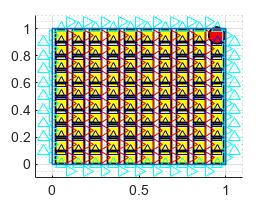

draw();
saveas(gcf,'domain_and_grid','png')

#### Define initial conditions

dt=CFL*dx/u;
set_BC(BCType);
[qold,pold] = set_IC(ICType);
A = advec(qold);
Aold = A;
LqbcOld = lap_bc();

#### Time marching starts

time = 0;
rMax = zeros(itmax,1);
count = 0;
tol = 1e-7;
isave = 50;
disp("Iteration: " + dt);

Iteration: 0.001


for it = 2:itmax 
    % solving for intermediate velocity
    A = advec(qold);
    Lqbc = lap_bc();
    Sx = Sfunc(qold);
    r1 = Sx - (dt/2)*(3*A - Aold) + (dt*nu/2)*(Lqbc + LqbcOld);
    qF = cg(qold,r1,1); % qF intermediate velocity
    Dqbc = div_bc();
    r2 = (1/dt)*div(qF) - (1/dt)*Dqbc;
    p = cg(pold,r2,2); % solving for pressure
    q = qF - dt*Rinv(grad(p)); % projection step
    resiudal = q - qold;
    qold = q;
    pold = p;
    Aold = A;
    LqbcOld = Lqbc;
    rMax(it) = ((rms((resiudal))));
    if(abs(rMax(it))<tol) 
        rMaxNew = rMax(2:it);
        break;
    end 
    if(mod(it,isave)==0)
        saveResuts(p,q,rMax,it)
    end
    disp("Iteration: "+ it);
end

Iteration: 2
Iteration: 3
Iteration: 4
Iteration: 5
Iteration: 6
Iteration: 7
Iteration: 8
Iteration: 9
Iteration: 10
Iteration: 11
Iteration: 12
Iteration: 13
Iteration: 14
Iteration: 15
Iteration: 16
Iteration: 17
Iteration: 18
Iteration: 19
Iteration: 20
Iteration: 21
Iteration: 22
Iteration: 23
Iteration: 24
Iteration: 25
Iteration: 26
Iteration: 27
Iteration: 28
Iteration: 29
Iteration: 30
Iteration: 31
Iteration: 32
Iteration: 33
Iteration: 34
Iteration: 35
Iteration: 36
Iteration: 37
Iteration: 38
Iteration: 39
Iteration: 40
Iteration: 41
Iteration: 42
Iteration: 43
Iteration: 44
Iteration: 45
Iteration: 46
Iteration: 47
Iteration: 48
Iteration: 49
Iteration: 50
Iteration: 51
Iteration: 52
Iteration: 53
Iteration: 54
Iteration: 55
Iteration: 56
Iteration: 57
Iteration: 58
Iteration: 59
Iteration: 60
Iteration: 61
Iteration: 62
Iteration: 63
Iteration: 64
Iteration: 65
Iteration: 66
Iteration: 67
Iteration: 68
Iteration: 69
Iteration: 70
Iteration: 71
Iteration: 72
Iteration: 73


Ploting and saving the final results

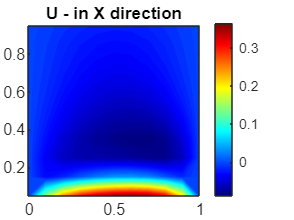

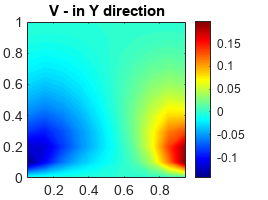

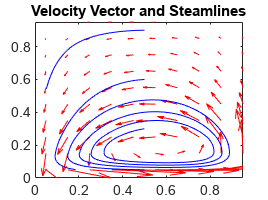

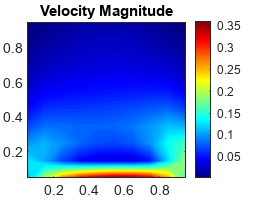

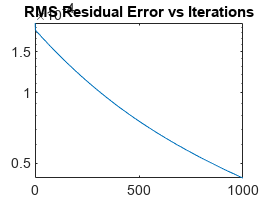

rMaxNew = rMax(2:it);
saveResuts(p,q,rMaxNew,it);
drawresult(p,q,rMaxNew);

## Necessary functions

======================================================================

### Calculating the size of u, v and p

Both the x- and y- component of the velocity is piled-up in one column variable u.

function setup_vars
global iu iv ip m n Np Nq Nu Nv dx dy xu yu xv yv xp yp cornerX cornerY Lx Ly
Lx = 1; Ly = 1;
cornerX = 0; cornerY = 0;
dx = Lx/m; dy = Ly/n;
Nu = (m-1)*n; % number of u
Nv = m*(n-1); % number of v
Nq = Nu + Nv; % number of q = pile up of u and v
Np = m*n - 1;
iu = zeros(m,n);
iv = zeros(m,n);
count = 0;
for i = 2:m
    for j = 1:n
        count = count+1;
        iu(i,j) = count;
    end
end
if (count~=Nu)
    error('setup_vars: iu have some problems');
end
for i = 1:m
    for j = 2:n
        count=count+1;
        iv(i,j)=count;
    end
end
if (count~=Nq)
    error('setup_vars:some problems with iv')
end
count = 0;
for i = 1:m
    for j = 1:n
        if ~(i==m && j==n) % pinned P(m,n)
            count = count+1;
            ip(i,j) = count;
        end
    end
end
if (count~=Np)
    error('setup_vars:ip is wrong')
end
%============== U ==================
xu = zeros(1,m+1);
yu  =zeros(1,n);
for i = 1:m
        xu(i)=((i-1)*dx)+cornerX;
end
for j = 1:n
        yu(j)=((j-1)*dy)+dy/2+cornerY;
end
xu(m+1) = cornerX+Lx;
%============== P ==================
for i = 1:m
    xp(i)=((i-1)*dx)+dx/2+cornerX;
end
for j = 1:n
    yp(j)=((j-1)*dy)+dy/2+cornerY;
end
%============== V ==================
xv = zeros(1,m);
yv = zeros(1,n+1);
for i = 1:m
        xv(i)=((i-1)*dx)+dx/2+cornerX;
end
for j = 1:n
        yv(j)=(j-1)*dy+cornerY;
end
yv(n+1) = cornerY+Ly;
end

### Plotting the domain with annotations

function draw()
global iu iv ip m n Re dt nq dx dy Lx Ly cornerX cornerY
figure();
hold on

% Pressure
for i = 1:m
    for j = 1:n
        plot(((i-1)*dx)+dx/2+cornerX,((j-1)*dy)+dy/2+cornerY,'bs', ...
            'LineWidth',1,...
            'MarkerEdgeColor','k',...
            'MarkerFaceColor',[1 1 0],...
            'MarkerSize',10)
    end
end

i = m; j = n;
plot(((i-1)*dx)+dx/2+cornerX,((j-1)*dy)+dy/2+cornerY,'ro', ...
    'LineWidth',1,...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[1 0 0],...
    'MarkerSize',10)


%U
for i = 2:m
    for j = 1:n
        plot(((i-1)*dx)+cornerX,((j-1)*dy)+dy/2+cornerY,'r>')
    end
end
%V
for i = 1:m
    for j=2:n
        plot(((i-1)*dx)+dx/2+cornerX,(j-1)*dy+cornerY,'b^')
    end
end

%Left U and V
i = 1; %U
for j=1:n
    plot(((i-1)*dx),((j-1)*dy)+dy/2,'c>')
end
i = 0; %V
for j=2:n
    plot(((i-1)*dx)+dx/2,(j-1)*dy,'c^')
end

%Right U and V
i = m+1; %U
for j=1:n
    plot(((i-1)*dx),((j-1)*dy)+dy/2,'c>')
end
i = m+1; %V
for j=2:n
    plot(((i-1)*dx)+dx/2,(j-1)*dy,'c^')
end

%Bottom U and V
j = 0; %U
for i=2:m
    plot(((i-1)*dx),((j-1)*dy)+dy/2,'c>')
end
j = 1; %V
for i=1:m
    plot(((i-1)*dx)+dx/2,(j-1)*dy,'c^')
end

%Top U and V
j = n+1; %U
for i=2:m
    plot(((i-1)*dx),((j-1)*dy)+dy/2,'c>')
end
j = n+1; %V
for i=1:m
    plot(((i-1)*dx)+dx/2,(j-1)*dy,'c^')
end

% Domain
plot([cornerX cornerX+Lx cornerX+Lx cornerX cornerX], ...
    [cornerY cornerY cornerY+Ly cornerY+Ly cornerY],'LineWidth',1)

axis([cornerX-dx cornerX+Lx+dx cornerY-dy cornerY+Ly+dy])
hold off
grid on
grid minor
end


### Setting up initial value of velocity

For uniform flow, $u = 1$.

For zero velocity, a very small velocity $u=1e^{-5}$ is given instead of zero velocity so that initial timestep does not diverge.

function [q,p] = set_IC(ICType) % Initial Coditions
global m n iu iv Nq Np ip

q=zeros(Nq,1);
p=zeros(Np,1);

if (ICType==0)
    for i= 2:m
        for j = 1:n
            q(iu(i,j)) = 0.0001;
        end
    end
    for i= 1:m
        for j = 2:n
            q(iv(i,j)) = 0;
        end
    end
elseif (ICType==1) %uniform flow
    for i= 2:m
        for j = 1:n
            q(iu(i,j)) = 0.8;
        end
    end
    for i= 1:m
        for j = 2:n
            q(iv(i,j)) = 0;
        end
    end
elseif (ICType==2)
    for i= 2:m
        for j = 1:n
            q(iu(i,j)) = 1;
        end
    end
    for i= 1:m
        for j = 2:n
            q(iv(i,j)) = 0;
        end
    end
    for i= 4:12
        for j = (n/2)-4:(n/2)+4
            q(iu(i,j)) = 0.8;
        end
    end    
elseif (ICType==3)
    for i= 2:m
        for j = 1:n
            q(iu(i,j)) = 1;
        end
    end
    for i= 1:m
        for j = 2:n
            q(iv(i,j)) = 0;
        end
    end
    i=8;
    j=8;
            q(iu(i,j)) = 5;
            q(iu(i,j+1)) = -5;
            q(iv(i-1,j)) = -5;
            q(iv(i,j)) = 5;
end
end

### Setting up boundary conditions

Type 4 is base tank excitation

function set_BC(boundaryConditionType)
global iu iv ip m n Np Nq Nu Nv dt
global vin uin uout vout
global utop vtop ubottom vbottom
% BC

if(boundaryConditionType==0) % all BC are zero
    uin = zeros(n,1);
    vin = zeros(n,1); 
    uout = zeros(n,1);
    vout = zeros(n,1); 
    utop= zeros(m,1); 
    vtop=zeros(m,1);
    ubottom= zeros(m,1);
    vbottom=zeros(m,1);    
elseif(boundaryConditionType==1) % unit x-velocity
    uin = ones(n,1);
    vin = zeros(n,1); 
    uout = ones(n,1);
    vout = zeros(n,1);
    utop= ones(m,1); 
    vtop=zeros(m,1);
    ubottom= ones(m,1);
    vbottom=zeros(m,1);
elseif(boundaryConditionType==2) %linear velocity profile
    uin = zeros(n,1);
    uout = zeros(n,1);
    utop = ones(m,1);
    ubottom = zeros(m,1);
    for i=1:n
        uin(i)=i/n;
        uout(i)=i/n;
    end
    vin = zeros(n,1); 
    vout = zeros(n,1);
    vtop=zeros(m,1);
    vbottom=zeros(m,1);
elseif(boundaryConditionType==3)
    uin = zeros(n,1);
    uout = ones(n,1);
    utop = ones(m,1);
    ubottom = zeros(m,1);
    for j=1:n
        uin(j)=j/n;
    end
    vin = zeros(n,1);
    vbottom=zeros(m,1);
    vout = zeros(n,1);
    vtop=zeros(m,1);
    for i=1:m
        vbottom(i)=(m-i)/m;
    end
elseif(boundaryConditionType==4) % base tank excitation
    uin = zeros(n,1);
    vin = zeros(n,1); 
    uout = zeros(n,1);
    vout = zeros(n,1);
    utop= zeros(m,1); % Top surface has unit x-velocity only
    vtop = zeros(m,1);
    ubottom = cos(1 * dt) * ones(m, 1);
    vbottom = zeros(m,1);   
elseif(boundaryConditionType==5) % Uniform flow in upward direction
    uin = zeros(n,1);
    vin = ones(n,1); 
    uout = zeros(n,1);
    vout = ones(n,1);
    utop = zeros(m,1); 
    vtop = ones(m,1);
    ubottom = zeros(m,1);
    vbottom = ones(m,1);
elseif(boundaryConditionType==6) % uniform flow at 45 angle
    uin = ones(n,1);
    vin = ones(n,1);
    uout = ones(n,1);
    vout = ones(n,1); 
    utop = ones(m,1);
    vtop = ones(m,1);
    ubottom = ones(m,1);
    vbottom = ones(m,1);
end
end

### Nonlinear advective terms - divergence form

function A = advec(q) % nonlinear advective terms - divergence form
global iu iv Nq m n dx dy uin uout utop ubottom vin vout vbottom vtop
A = zeros(Nq,1);

%--------------  X  --------------
for i = 3:m-1
    for j = 2:n-1
        A(iu(i,j))= (1/(4*dx))*( - (q(iu(i-1,j)) + q(iu(i,j)))^2 + (q(iu(i,j))+q(iu(i+1,j)))^2 ) ...
            + (1/(4*dy))*( -( (q(iv(i-1,j))+q(iv(i,j))) * (q(iu(i,j-1))+q(iu(i,j))) ) ...
            + ((q(iv(i-1,j+1))+q(iv(i,j+1))) * (q(iu(i,j))+q(iu(i,j+1))) ) );
    end
end
%Boundary
%left
i = 2;
for j = 2:n-1
    A(iu(i,j))= (1/(4*dx))*( - ( uin(j) + q(iu(i,j)))^2 + (q(iu(i,j))+q(iu(i+1,j)))^2 ) ...
        + (1/(4*dy))*( -( (q(iv(i-1,j))+q(iv(i,j))) * (q(iu(i,j-1))+q(iu(i,j))) ) ...
        + ((q(iv(i-1,j+1))+q(iv(i,j+1))) * (q(iu(i,j))+q(iu(i,j+1))) ) );
end
%right
i = m;
for j = 2:n-1
    A(iu(i,j))= (1/(4*dx))*( - ( q(iu(i-1,j)) + q(iu(i,j)))^2 + (q(iu(i,j))+uout(j))^2 ) ...
        + (1/(4*dy))*( -( (q(iv(i-1,j))+q(iv(i,j))) * (q(iu(i,j-1))+q(iu(i,j))) ) ...
        + ((q(iv(i-1,j+1))+q(iv(i,j+1))) * (q(iu(i,j))+q(iu(i,j+1))) ) );
end
%bottom
j = 1;
for i = 3:m-1
    A(iu(i,j))= (1/(4*dx))*( - ( q(iu(i-1,j)) + q(iu(i,j)))^2 + (q(iu(i,j))+q(iu(i+1,j)))^2 ) ...
        + (1/(4*dy))*( -( (vbottom(i-1)+vbottom(i)) * (ubottom(i)+q(iu(i,j))) ) ...
        + ((q(iv(i-1,j+1))+q(iv(i,j+1))) * (q(iu(i,j))+q(iu(i,j+1))) ) );
end
%top
j = n;
for i = 3:m-1
    A(iu(i,j))= (1/(4*dx))*(-(q(iu(i-1,j)) + q(iu(i,j)))^2 + (q(iu(i,j))+q(iu(i+1,j)))^2 ) ...
        + (1/(4*dy))*( -( (q(iv(i-1,j))+q(iv(i,j))) * (q(iu(i,j-1))+q(iu(i,j))) ) ...
        + ((vtop(i-1)+vtop(i)) * (q(iu(i,j))+utop(i)) ) );
end
%Corners
%topleft
j = n;
i = 2;
A(iu(i,j))= (1/(4*dx))*( - (uin(j) + q(iu(i,j)))^2 + (q(iu(i,j))+q(iu(i+1,j)))^2 ) ...
    + (1/(4*dy))*( -( (q(iv(i-1,j))+q(iv(i,j))) * (q(iu(i,j-1))+q(iu(i,j))) ) ...
    + ((vtop(i-1)+vtop(i)) * (q(iu(i,j))+utop(i)) ) );
%topright
j = n;
i = m;
A(iu(i,j))= (1/(4*dx))*( - (q(iu(i-1,j)) + q(iu(i,j)))^2 + (q(iu(i,j))+uout(j))^2 ) ...
    + (1/(4*dy))*( -( (q(iv(i-1,j))+q(iv(i,j))) * (q(iu(i,j-1))+q(iu(i,j))) ) ...
    + ((vtop(i-1)+vtop(i)) * (q(iu(i,j))+utop(i)) ) );
%bottomleft
j = 1;
i = 2;
A(iu(i,j))= (1/(4*dx))*( - ( uin(j) + q(iu(i,j)))^2 + (q(iu(i,j))+q(iu(i+1,j)))^2 ) ...
    + (1/(4*dy))*( -( (vbottom(i-1)+vbottom(i)) * (ubottom(i)+q(iu(i,j))) ) ...
    + ((q(iv(i-1,j+1))+q(iv(i,j+1))) * (q(iu(i,j))+q(iu(i,j+1))) ) );
%bottomright
i = m;
j = 1;
A(iu(i,j))= (1/(4*dx))*( - ( q(iu(i-1,j)) + q(iu(i,j)))^2 + (q(iu(i,j))+uout(j))^2 ) ...
    + (1/(4*dy))*( -( (vbottom(i-1)+vbottom(i)) * (ubottom(i)+q(iu(i,j))) ) ...
    + ((q(iv(i-1,j+1))+q(iv(i,j+1))) * (q(iu(i,j))+q(iu(i,j+1))) ) );

%--------------  Y  --------------

for i = 2:m-1
    for j = 3:n-1
        A(iv(i,j))= (1/(4*dx))*( -( (q(iu(i,j-1))+q(iu(i,j))) * (q(iv(i-1,j))+q(iv(i,j))) ) ...
            + ((q(iu(i+1,j-1))+q(iu(i+1,j))) * (q(iv(i,j))+q(iv(i+1,j))) ) ) ...
            + (1/(4*dy))*( - (q(iv(i,j-1)) + q(iv(i,j)))^2 + (q(iv(i,j))+q(iv(i,j+1)))^2 );
    end
end
%Boundary
%left
i = 1;
for j = 3:n-1
    A(iv(i,j))= (1/(4*dx))*( -( (uin(j-1)+uin(j)) * ( vin(j) + q(iv(i,j))) ) ...
        + ((q(iu(i+1,j-1))+q(iu(i+1,j))) * (q(iv(i,j))+q(iv(i+1,j))) ) ) ...
        + (1/(4*dy))*( - (q(iv(i,j-1)) + q(iv(i,j)))^2 + (q(iv(i,j))+q(iv(i,j+1)))^2 );
end
%right
i = m;
for j = 3:n-1
    A(iv(i,j))= (1/(4*dx))*( -( (q(iu(i,j-1))+q(iu(i,j))) * (q(iv(i-1,j))+q(iv(i,j))) ) ...
        + ((uout(j-1)+uout(j)) * (q(iv(i,j))+vout(j)) ) ) ...
        + (1/(4*dy))*( - (q(iv(i,j-1)) + q(iv(i,j)))^2 + (q(iv(i,j))+q(iv(i,j+1)))^2 );
end
%bottom
j=2;
for i = 2:m-1
    A(iv(i,j))= (1/(4*dx))*( -( (q(iu(i,j-1))+q(iu(i,j))) * (q(iv(i-1,j))+q(iv(i,j))) ) ...
        + ((q(iu(i+1,j-1))+q(iu(i+1,j))) * (q(iv(i,j))+q(iv(i+1,j))) ) ) ...
        + (1/(4*dy))*( - ( vbottom(i) + q(iv(i,j)))^2 + (q(iv(i,j))+q(iv(i,j+1)))^2 );
end
%top
j=n;
for i = 2:m-1
    A(iv(i,j))= (1/(4*dx))*( -( (q(iu(i,j-1))+q(iu(i,j))) * (q(iv(i-1,j))+q(iv(i,j))) ) ...
        + ((q(iu(i+1,j-1))+q(iu(i+1,j))) * (q(iv(i,j))+q(iv(i+1,j))) ) ) ...
        + (1/(4*dy))*( - ( q(iv(i,j-1)) + q(iv(i,j)))^2 + (q(iv(i,j))+ vtop(i))^2 );
end
%corners
%left-bottom
i = 1;
j = 2;
A(iv(i,j))= (1/(4*dx))*( -( (uin(j-1)+uin(j)) * ( vin(j) + q(iv(i,j))) ) ...
    + ((q(iu(i+1,j-1))+q(iu(i+1,j))) * (q(iv(i,j))+q(iv(i+1,j))) ) ) ...
    + (1/(4*dy))*( - (vbottom(i) + q(iv(i,j)))^2 + (q(iv(i,j))+q(iv(i,j+1)))^2 );
%left-top
i = 1;
j = n;
A(iv(i,j))= (1/(4*dx))*( -( (uin(j-1)+uin(j)) * ( vin(j) + q(iv(i,j))) ) ...
    + ((q(iu(i+1,j-1))+q(iu(i+1,j))) * (q(iv(i,j))+q(iv(i+1,j))) ) ) ...
    + (1/(4*dy))*( - (q(iv(i,j-1)) + q(iv(i,j)))^2 + (q(iv(i,j))+ vtop(i))^2 );

%right bottom
i = m;
j = 2;
A(iv(i,j))= (1/(4*dx))*( -( (q(iu(i,j-1))+q(iu(i,j))) * (q(iv(i-1,j))+q(iv(i,j))) ) ...
    + ((uout(j-1)+uout(j)) * (q(iv(i,j))+vout(j)) ) ) ...
    + (1/(4*dy))*( - (vbottom(i) + q(iv(i,j)))^2 + (q(iv(i,j))+q(iv(i,j+1)))^2 );
%right top
i = m;
j = n;
A(iv(i,j)) = (1/(4*dx))*( -( (q(iu(i,j-1))+q(iu(i,j))) * (q(iv(i-1,j))+q(iv(i,j))) ) ...
    + ((uout(j-1)+uout(j)) * (q(iv(i,j))+vout(j)) ) ) ...
    + (1/(4*dy))*( - (q(iv(i,j-1)) + q(iv(i,j)))^2 + (q(iv(i,j))+ vtop(i))^2 );
end

### Conjugate Gradient Solver

Solves for $\textrm{Ax}=\mathit{\mathbf{b}}$

function x = cg(x0,b,eqNo)
% eqNo = 1 is for velocity
% eqNo = 2 is for pressure
x = x0;
imax = length(x);
eps =  1e-5;
%disp("Warning: hard coding the value of eps = " + eps)
r = b-Atimes(x,eqNo);%A*x;
d = r;
delta_new = sum(r.^2);%r'*r;
delta0 = delta_new;

for i = 1:imax
    q = Atimes(d,eqNo);%A*d;
    alpha = delta_new/sum(d.*q);
    x = x + alpha*d;

    if mod(i,50)==0
        r = b - Atimes(x,eqNo);%A*x;
    else
        r = r - alpha * q;
    end

    delta_old = delta_new;
    delta_new = sum(r.^2);
    beta = delta_new/delta_old;
    d = r + beta*d;

    if ((delta_new < eps^2 *delta0))
        break
    end
end
end

Conjugate gradient solvers coeffcient

function Ax = Atimes(x,eqNo)
% conjugate gradient solvers coeffcient on the left hand side
global dt nu
if (eqNo==1)
    Ax = x - 0.5 * dt * nu * lap(x);
elseif (eqNo==2)
    Ax = div(Rinv(grad(x)));
else
    error('Achtung!')
end
end

Getting the inverse of matrix, $R = I - \frac{\Delta t}{2} \nu L$

function Rix = Rinv(R)
global dt nu
order = 2;
%disp("Warning: hard coding the order to " + order)
if(order==1)
    Rix = R;
elseif (order==2)
    Rix = R + dt/2*nu*lap(R);
elseif (order == 3)
    Lx = lap(R);
    Rix = R + dt/2*nu*lap(R) + (dt*nu/2)^2 * lap(Lx);
else
    error('in RIx')
end
end

S term, $S = I + \frac{\Delta t}{2} \nu L$

function Sx = Sfunc(x)
global dt nu
Sx = x + (dt/2)*nu*lap(x);
end

### Divergence operator

function Dq = div(q)
global iu iv ip Np m n dx dy
Dq = zeros (Np,1);
for j = 2:n-1
    for i = 2:m-1
        Dq(ip(i,j)) = ( q(iu(i+1,j)) - q(iu(i,j)) )/dx ...
            + ( q(iv(i,j+1)) - q(iv(i,j)) )/dy;
    end
end

% Bottom
j=1;
for i = 2:m-1
    Dq(ip(i,j)) = ( q(iu(i+1,j)) - q(iu(i,j)) )/dx ...  %
        + ( q(iv(i,j+1)))/dy;
end
% Top
j=n;
for i = 2:m-1
    Dq(ip(i,j)) = ( q(iu(i+1,j)) - q(iu(i,j)) )/dx ...  %
        + ( 0 - q(iv(i,j)) )/dy;
end
% Inlet
i = 1;
for j = 2:n-1
    Dq(ip(i,j)) = ( q(iu(i+1,j)) )/dx ...
        + ( q(iv(i,j+1)) - q(iv(i,j)) )/dy;
end
% Outlet
i = m;
for j = 2:n-1
    Dq(ip(i,j)) = (0 - q(iu(i,j)) )/dx ...
        + ( q(iv(i,j+1)) - q(iv(i,j)) )/dy;
end
%corners
% Inlet - Bottom
i = 1; j = 1;
Dq(ip(i,j)) = ( q(iu(i+1,j)) )/dx ...
    + ( q(iv(i,j+1)) )/dy;
% Outlet - Bottom
i = m; j = 1;
Dq(ip(i,j)) = ( 0 - q(iu(i,j))  )/dx ...
    + ( q(iv(i,j+1)) )/dy;
% Inlet - Top
i = 1; j = n;
Dq(ip(i,j)) = ( q(iu(i+1,j)) - 0  )/dx ...
    + ( 0 - q(iv(i,j)) )/dy;
% Outlet - Top -> pinned
end

Divergence operator on boundary

function Dqbc = div_bc()
global vtop vbottom uin uout Np m n ip dx dy

Dqbc=zeros(Np,1);

% Bottom
j = 1;
for i = 2:m-1
    Dqbc(ip(i,j)) = -vbottom(i)/dy;
end
% Top
j = n;
for i = 2:m-1
    Dqbc(ip(i,j)) = vtop(i)/dy;
end
% Inlet
i = 1;
for j = 2:n-1
    Dqbc(ip(i,j)) = -uin(j)/dx;
end
% Outlet
i = m;
for j = 2:n-1
    Dqbc(ip(i,j)) = uout(j)/dx;
end
%corners
% Inlet - Bottom
i = 1; j=1;
Dqbc(ip(i,j)) = - uin(j)/dx - vbottom(i)/dy;
% Outlet - Bottom
i = m; j=1;
Dqbc(ip(i,j)) = uout(j)/dx - vbottom(i)/dy;
% Inlet - Top
i = 1; j=n;
Dqbc(ip(i,j)) = -uin(j)/dx + vtop(i)/dy;
% Outlet - Top
% i = m; j=n;
% Dqbc(ip(i,j)) = uout(j)/dx + vtop(i)/dy; %ip(m,n) does not exist
end

### Evaluating gradient operator

function Gp = grad(p)
global iu iv ip Np m n dx dy
Gp = zeros (Np,1);
for j = 1:n
    for i = 2:m-1
        Gp(iu(i,j))= (p(ip(i,j)) - p(ip(i-1,j)))/dx;
    end
end
i=m;
for j = 1:n-1
    Gp(iu(i,j))= (p(ip(i,j)) - p(ip(i-1,j)))/dx;
end
i=m; j=n;  Gp(iu(i,j))= (  - p(ip(i-1,j)))/dx; %pined value
for j = 2:n
    for i = 1:m-1
        Gp(iv(i,j))= (p(ip(i,j)) - p(ip(i,j-1)))/dy;
    end
end
i=m;
for j = 2:n-1
    Gp(iv(i,j))= (p(ip(i,j)) - p(ip(i,j-1)))/dy;
end
i=m; j=n; Gp(iv(i,j))= (    - p(ip(i,j-1)))/dy; %pined value
end

### Evaluating Laplace operator

function Lq = lap(q)
global iu iv Nq m n dx dy

Lq = zeros(Nq,1);
% X-direction
for j= 2:n-1
    for i = 3:m-1
        Lq(iu(i,j)) = ( q(iu(i-1,j)) - 2*q(iu(i,j)) + q(iu(i+1,j)))/dx^2 ...
            + ( q(iu(i,j-1)) - 2*q(iu(i,j)) + q(iu(i,j+1)))/dy^2;
    end
end

%inlet
i = 2;
for j= 2:n-1
    Lq(iu(i,j))= ( 0 - 2*q(iu(i,j)) + q(iu(i+1,j)))/dx^2 ... %uin(j)
        + ( q(iu(i,j-1)) - 2*q(iu(i,j)) + q(iu(i,j+1)))/dy^2;
end
%outlet
i = m;
for j= 2:n-1
    Lq(iu(i,j))= ( q(iu(i-1,j)) - 2*q(iu(i,j)) + 0 )/dx^2 ...  %uout(j)
        + ( q(iu(i,j-1)) - 2*q(iu(i,j)) + q(iu(i,j+1)) )/dy^2;
end
%bottom
j= 1;
for i = 3:m-1
    Lq(iu(i,j))= (q(iu(i-1,j))-2*q(iu(i,j)) +q(iu(i+1,j)))/dx^2 ...
        +( 0 - 2*q(iu(i,j)) +q(iu(i,j+1)))/dy^2; %ubottom(i)
end
%top
j= n;
for i = 3:m-1
    Lq(iu(i,j))= (q(iu(i-1,j))-2*q(iu(i,j)) +q(iu(i+1,j)))/dx^2 ...
        + (q(iu(i,j-1))-2*q(iu(i,j)) + 0 )/dy^2; %utop(i)
end

% Y direction
for j= 3:n-1
    for i = 2:m-1
        Lq(iv(i,j))= (q(iv(i-1,j))-2*q(iv(i,j)) +q(iv(i+1,j)))/dx^2 ...
            + (q(iv(i,j-1))-2*q(iv(i,j)) +q(iv(i,j+1)))/dy^2;
    end
end
%inlet
i = 1;
for j= 3:n-1
    Lq(iv(i,j)) = ( 0 - 2*q(iv(i,j)) + q(iv(i+1,j)))/dx^2 ... %vin(j)
        + ( q(iv(i,j-1)) - 2*q(iv(i,j)) + q(iv(i,j+1)))/dy^2;
end
%outlet
i = m;
for j= 3:n-1
    Lq(iv(i,j)) = ( q(iv(i-1,j)) - 2*q(iv(i,j)) + 0 )/dx^2 ... %vout(j)
        + ( q(iv(i,j-1)) - 2*q(iv(i,j)) + q(iv(i,j+1)) )/dy^2;
end
%bottom
j = 2;
for i = 2:m-1
    Lq(iv(i,j))= (q(iv(i-1,j)) - 2*q(iv(i,j)) + q(iv(i+1,j)))/dx^2 ...
        +(  0 - 2*q(iv(i,j)) + q(iv(i,j+1)))/dy^2; %vbottom(i)
end
%top
j = n;
for i = 2:m-1
    Lq(iv(i,j))= (q(iv(i-1,j)) - 2*q(iv(i,j)) + q(iv(i+1,j)))/dx^2 ...
        + (q(iv(i,j-1)) - 2*q(iv(i,j)) + 0 )/dy^2; %utop(i)
end
%Corners - U
%inlet - top
i = 2; j = n;
Lq(iu(i,j))= ( 0 - 2*q(iu(i,j)) + q(iu(i+1,j)))/dx^2 ... %uin(j)
    + ( q(iu(i,j-1)) - 2*q(iu(i,j)) + 0)/dy^2; %utop(i)
%outlet - top
i = m; j = n;
Lq(iu(i,j))= ( q(iu(i-1,j)) - 2*q(iu(i,j)) + 0)/dx^2 ... %uout(j)
    + ( q(iu(i,j-1)) - 2*q(iu(i,j)) + 0 )/dy^2; %utop(i)
%bottom - inlet
j = 1; i = 2;
Lq(iu(i,j))= (0- 2*q(iu(i,j)) + q(iu(i+1,j)))/dx^2 ... %uin(j)
    +(0 - 2*q(iu(i,j)) + q(iu(i,j+1)))/dy^2; %ubottom(i)
%bottom outlet
j = 1; i = m;
Lq(iu(i,j))= ( q(iu(i-1,j)) - 2*q(iu(i,j)) +0 )/dx^2 ... %uout(j)
    + ( 0 - 2*q(iu(i,j)) + q(iu(i,j+1) ))/dy^2 ; %ubottom(i)

%Corners - V
%inlet-top
i = 1; j = n;
Lq(iv(i,j)) = (0- 2*q(iv(i,j)) + q(iv(i+1,j)))/dx^2 ...%vin(j)
    + ( q(iv(i,j-1)) - 2*q(iv(i,j)) +0)/dy^2; % vtop(i)
%outlet - top
i = m; j = n;
Lq(iv(i,j)) = ( q(iv(i-1,j)) - 2*q(iv(i,j)) +0)/dx^2 ...%vout(j)
    + ( q(iv(i,j-1)) - 2*q(iv(i,j)) +0)/dy^2;%vtop(i)
%bottom - left
j = 2; i = 1;
Lq(iv(i,j))= (0- 2*q(iv(i,j)) + q(iv(i+1,j)))/dx^2 ... %vin(j)
    +(0- 2*q(iv(i,j)) + q(iv(i,j+1)))/dy^2;%vbottom(i)
%bottom - right
j = 2; i = m;
Lq(iv(i,j))= (q(iv(i-1,j)) - 2*q(iv(i,j)) +0)/dx^2 ... %vout(j)
    + (0- 2*q(iv(i,j)) + q(iv(i,j+1)) )/dy^2; %vbottom(i)
end

Laplace operator on boundary

function Lqbc = lap_bc() 
global iu iv dx dy Nq m n uin uout utop ubottom vin vout vtop vbottom
Lqbc=zeros(Nq,1);

% ============= u velocity ================
% Boundaries
%inlet
i = 2;
for j= 2:n-1
    Lqbc(iu(i,j)) = uin(j)/dx^2;
end
%outlet
i = m;
for j= 2:n-1
    Lqbc(iu(i,j)) = uout(j)/dx^2;
end
%bottom
j = 1;
for i = 3:m-1
    Lqbc(iu(i,j)) = ubottom(i)/dy^2; %
end
%top
j = n;
for i = 3:m-1
    Lqbc(iu(i,j)) = utop(i)/dy^2;
end
%Corners

%inlet - top
i = 2; j = n;
Lqbc(iu(i,j))= uin(j)/dx^2 + utop(i)/dy^2; %utop(i)
%outlet - top
i = m; j = n;
Lqbc(iu(i,j))= uout(j)/dx^2 + utop(i)/dy^2; %utop(i)
%bottom - inlet
j = 1; i = 2;
Lqbc(iu(i,j))= uin(j)/dx^2 + ubottom(i)/dy^2; %ubottom(i)
%bottom outlet
j = 1; i = m;
Lqbc(iu(i,j))= uout(j)/dx^2 + ubottom(i)/dy^2 ; %ubottom(i)

% ================ V velocity ============
%Boundaries
%inlet
i = 1;
for j= 3:n-1
    Lqbc(iv(i,j)) = vin(j)/dx^2;
end
%outlet
i = m;
for j = 3:n-1
    Lqbc(iv(i,j)) = vout(j)/dx^2;
end
%bottom
j = 2;
for i = 2:m-1
    Lqbc(iv(i,j)) = vbottom(i)/dy^2;
end
%top
j = n;
for i = 2:m-1
    Lqbc(iv(i,j)) = vtop(i)/dy^2;
end

% Corners
%inlet-top
i = 1; j = n;
Lqbc(iv(i,j)) = vin(j)/dx^2 + vtop(i)/dy^2;
%outlet - top
i = m; j = n;
Lqbc(iv(i,j)) = vout(j)/dx^2 + vtop(i)/dy^2;
%bottom - left
j = 2; i = 1;
Lqbc(iv(i,j))= vin(j)/dx^2 + vbottom(i)/dy^2;
%bottom - right
j = 2; i = m;
Lqbc(iv(i,j))= vout(j) /dx^2 +vbottom(i)/dy^2;

end

### Plotting and saving flow variables

Saving

function saveResuts(p,q,rMax,it)
global ip m n iu iv uin uout vbottom vtop xp yp xu yu xv yv Np Nq
filename=sprintf('results%d_%d_%d', m,n,it);
save(filename,'m','n','ip','iu','iv','p','q','Np','Nq', ...
    'uin','uout','vbottom','vtop','q','xp', 'yp', 'xu', ... 
    'yu', 'xv', 'yv', 'rMax');
end

Plotting p, u, v, streamlines with velocity vectors and rasidual

function drawresult(p, q, rMax)
global ip iu iv m n uin uout vbottom vtop xp xu xv yp yu yv Np Nq
%-------------- P  --------------
pimage = zeros(m,n);
for i = 1:m
    for j = 1:n
        if ~(i==m && j==n)
            pimage(i,j) = p(ip(i,j));
        end
    end
end
pimage(m,n)= p(ip(m,n-1));
pimage = pimage';
%pimage=flip(pimage,2);
figure(1)
[Xp,Yp] = meshgrid(xp,yp);
[~,hp] = contourf(Xp,Yp,pimage,100);
colormap jet;
colorbar;
set(hp,'LineColor','none');
title('Pressure');
xlabel('x/L');
ylabel('y/L');

%=============== U ======================================================
uimage = zeros(m+1,n);
Xu = zeros(m+1,n);
Yu = zeros(m+1,n);
for i=2:m
    for j=1:n
        uimage(i,j) = q(iu(i,j));
        Xu(i,j) = xu(i);
        Yu(i,j) = yu(j);
    end
end
i = 1;
for j=1:n
    uimage(i,j) = uin(j);
    Xu(i,j) = xu(i);
    Yu(i,j) = yu(j);
end
i = m+1;
for j = 1:n
    uimage(i,j) = uout(j);
    Xu(i,j) = xu(i);
    Yu(i,j) = yu(j);
end

figure(2)
%[Xu,Yu] = meshgrid(xu,yu);
[Cu,hu]=contourf(Xu,Yu,uimage,100);
colormap jet;
colorbar;
set(hu,'LineColor','none');
title('U - in X direction');
%=============== V ======================================================
vimage=zeros(m,n+1);
for i=1:m
    for j=2:n
        vimage(i,j) = q(iv(i,j));
        Xv(i,j) = xv(i);
        Yv(i,j) = yv(j);
    end
end
j=1;
for i=1:m
    vimage(i,j) = vbottom(i);
    Xv(i,j) = xv(i);
    Yv(i,j) = yv(j);
end
j=n+1;
for i=1:m
    vimage(i,j) = vtop(i);
    Xv(i,j) = xv(i);
    Yv(i,j) = yv(j);
end

figure(3)
[Cv,hv] = contourf(Xv,Yv,vimage,100);
colormap jet;
colorbar;
set(hv,'LineColor','none');
title('V - in Y direction');
%----------------------Velocity-----------------------------
[U,V,ipq] = find_cell_centered( q,iu, iv, ip, Np, m ,n, uin, uout, vbottom, vtop) ;

for i=1:m
    for j=1:n
            uV(i,j) = U(ipq(i,j));
            vV(i,j) = V(ipq(i,j));
            Velocity(i,j) = sqrt(U(ipq(i,j))^2 + V(ipq(i,j))^2);
    end
end

uV=uV';
vV=vV';
Velocity=Velocity';

figure(4);
nSkip = 1;
q = quiver(Xp(1:nSkip:end),Yp(1:nSkip:end),uV(1:nSkip:end),vV(1:nSkip:end));
axis([0 max(xp) 0 max(yp)])
title('Velocity Vector and Steamlines')
q.AutoScale = 'on';
q.AutoScaleFactor = 3;
q.Color = 'red';
starty = (0:0.3:1);
startx = 0.5*ones(size(starty));
streamline(Xp,Yp,uV,vV,startx,starty)

figure(5)
%----------------------Velocity-----------------------------
[~,hvel]=contourf(Xp,Yp,Velocity,100);
colormap jet;
colorbar;
set(hvel,'LineColor','none');
title('Velocity Magnitude')
%==========================================================================

figure(6)
semilogy(rMax)
title('RMS Residual Error vs Iterations')

end

Calculating several average quantities

function [ccU, ccV, ipq] = find_cell_centered( q,iu, iv, ip, Np, m ,n, uin, uout, vbottom, vtop)
ccU = zeros(Np+1,1);
ccV = zeros (Np+1,1);
ipq=ip;
ipq(m,n)=m*n;

for j = 2:n-1
    for i = 2:m-1
        ccU(ipq(i,j)) = ( q(iu(i+1,j)) + q(iu(i,j)) )/2;
    end
end

% Bottom
j=1;
for i = 2:m-1
    ccU(ipq(i,j)) = ( q(iu(i+1,j)) + q(iu(i,j)) )/2;
end
% Top
j=n;
for i = 2:m-1
    ccU(ipq(i,j)) = ( q(iu(i+1,j)) + q(iu(i,j)) )/2;
end
% Inlet
i = 1;
for j = 1:n
    ccU(ipq(i,j)) = ( uin(j) + q(iu(i+1,j)) )/2;
end
% Outlet
i = m;
for j = 1:n
    ccU(ipq(i,j)) = ( uout(j) + q(iu(i,j)) )/2;
end
%-------------V-----------------
for j = 2:n-1
    for i = 2:m-1
        ccV(ip(i,j)) = ( q(iv(i,j+1)) + q(iv(i,j)) )/2;
    end
end

% Bottom
j=1;
for i = 1:m
    ccV(ipq(i,j)) = ( vbottom(i) + q(iv(i,j+1)))/2;
end
% Top
j=n;
for i = 1:m
    ccV(ipq(i,j)) = ( vtop(i) + q(iv(i,j)) )/2;
end
% Inlet
i = 1;
for j = 2:n-1
    ccV(ipq(i,j)) = ( q(iv(i,j+1)) + q(iv(i,j)) )/2;
end
% Outlet
i = m;
for j = 2:n-1
    ccV(ipq(i,j)) = ( q(iv(i,j+1)) + q(iv(i,j)) )/2;
end
end